path = char("H:\data\LE14\LE14_231119");
ops = CodeJeff.BuildOps(path);
rawData = CodeJeff.BuildRawData(ops);

Only amplifier & digitalin file names are specified.
Load RawData for the second time.


backslashIdx = strfind(path, '\');
namaBase = path(backslashIdx(end)+1: end);
nameLoad = [namaBase '_data_base.mat'];
load(fullfile('C:\Users\412\Downloads', nameLoad), 'spikes', 'digTrig');
spk = spikes{1};
spk = spk.CorrectTrigger(digTrig(ops.forcTrigOrder(1)));

nameLoad = [namaBase, '_tracks_forced.mat'];
load(fullfile('C:\Users\412\Downloads', nameLoad), 'tracksForc');
track = tracksForc{1};
track = track.TrimTrack(rawData, ops.forcSeg(1), digTrig(ops.forcTrigOrder(1)));

spkCount = spk.SpikeHistcountFrame(track.frameSeries, ops.frameRate, ops.ampSampleRate);
speedIdx = track.SpeedIndex(8);
[nBin2D, frameHist, binnedFrame] = track.BinFrame2D(speedIdx, ops.binLength/track.pixelToCmRatio);
nUnit = size(spk.units, 1);
rateMap = cell(nUnit, 1);
for iUnit = 1: nUnit
    spkCountTmp = spkCount(:, iUnit);
    rateMap{iUnit} = zeros(nBin2D(1), nBin2D(2));
    for iBinX = 1: nBin2D(1)
        for iBinY = 1: nBin2D(2)
            nSpk = sum(spkCountTmp(binnedFrame{iBinX, iBinY} + ops.forcTrigFrame(1)));
            nFrame = frameHist(iBinX, iBinY);
            rateMap{iUnit}(iBinX, iBinY) = nSpk / (nFrame / track.frameRate);
        end
    end
end

rateMapSmooth = cell(size(rateMap));
sigma = 10*track.pixelToCmRatio;
kernel = 20;
gaussianKernel = fspecial('gaussian', [kernel, kernel], sigma);
for iUnit = 1: nUnit
    rateMapTmp = rateMap{iUnit};
    nanIdx = isnan(rateMapTmp);
    rateMapTmp(nanIdx) = 0;
    rateMapTmp = imfilter(rateMapTmp, gaussianKernel, 'conv', 'replicate');
    rateMapTmp(nanIdx) = nan;
    rateMapSmooth{iUnit} = rateMapTmp;
end

iPlot = 66

iPlot = 66

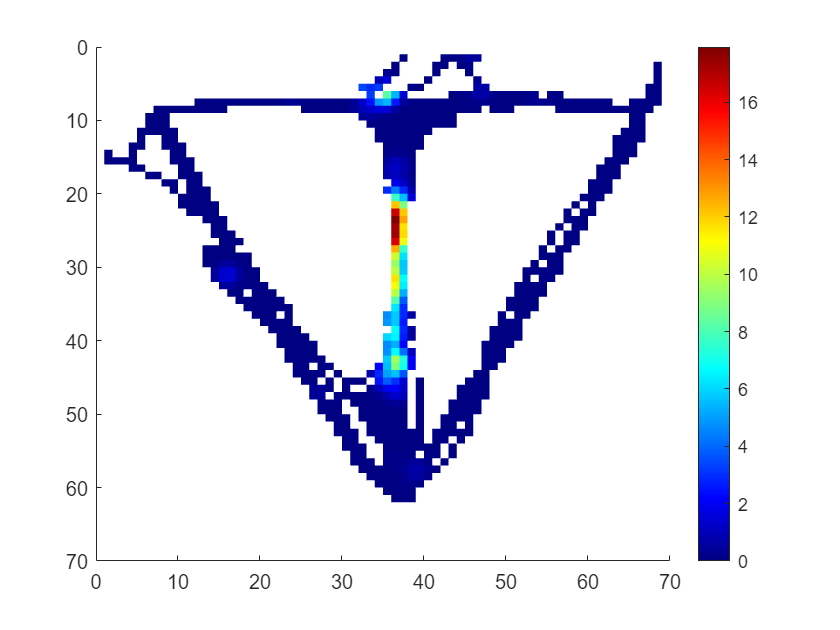

figure
hold on
matPlot = [rateMapSmooth{iPlot}' nan(nBin2D(2), 1)];
matPlot = [matPlot; nan(1, nBin2D(1)+1)];
pcolor(matPlot);
colorbar
colormap('jet')
shading flat
set(gca, 'ydir', 'reverse')